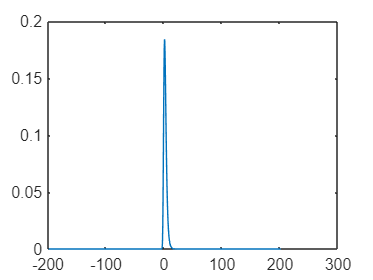

% PDF CDF of Gumbel Distribution for mu=1 and beta = 2
%and its variance
NUMBER_OF_STEPS = 100; %Per unit length
RANGE = 400;
ARRAY_SIZE = NUMBER_OF_STEPS*RANGE ;
x = zeros(1,ARRAY_SIZE);
y = zeros(1,ARRAY_SIZE);
z = zeros(1,ARRAY_SIZE);
var = 0;
mu = 1;
beta = 2;
mean = 0;
for i = 1:ARRAY_SIZE
    v = mu - RANGE/2 + i/NUMBER_OF_STEPS;
    x(i) = v; 
    t = (v-mu)/beta;
    y(i) = exp(-(t+exp(-t)))/beta;
    z(i+1) = z(i) + y(i)/NUMBER_OF_STEPS;
    mean = mean + x(i)*(y(i)/NUMBER_OF_STEPS);
end
mean;
for i= 1:ARRAY_SIZE
    var = var + (y(i)*(x(i)-mean)^2)/NUMBER_OF_STEPS;
end

plot(x,y);

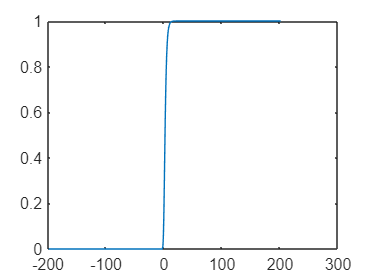


m = z(1,1:ARRAY_SIZE);
plot(x,m);


var 

var = 6.5797